# Visión por Computador - Sesión 5

    Ferran Velasco Olivera

    Joaquín Gómez Sánchez

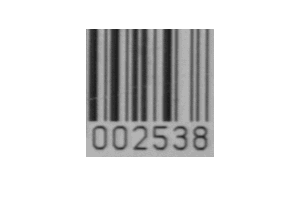

im = imread('n2538.tif');
imshow(im)

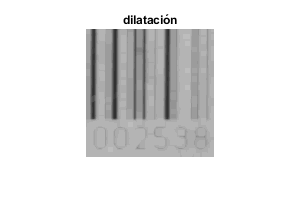


ee = strel('disk', 3);

dil = imdilate(im, ee);
ero = imerode(im,ee);
figure, imshow(dil), title('dilatación')

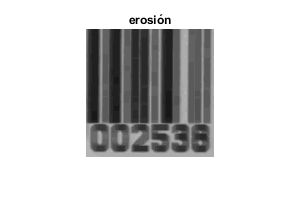

figure, imshow(ero), title('erosión')

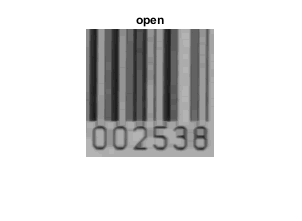


op = imopen(im, ee);
cl = imclose(im, ee);
figure, imshow(op), title('open')

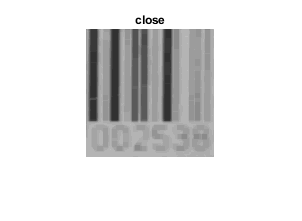

figure, imshow(cl), title('close')

## Eliminación de pequeñas estructuras blancas y negras

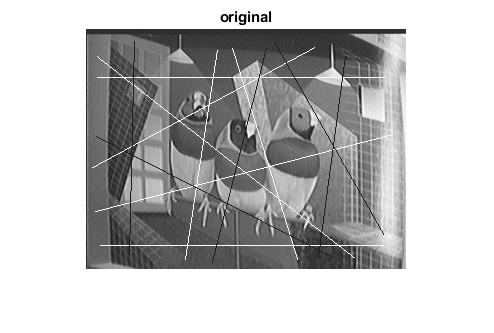

im = imread('Birds.tif');
imshow(im), title('original');

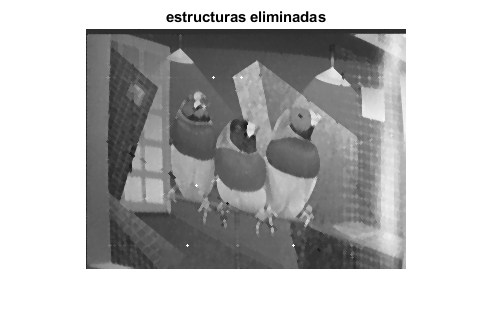


ee = strel('disk', 1);

im = imopen(im, ee);
im = imclose(im, ee);

figure, imshow(im), title('estructuras eliminadas')

## Determinar los contornos con dilatación y erosión

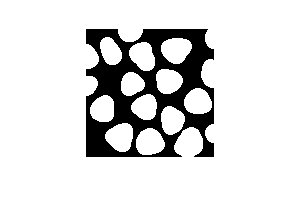

im = imread('blob3.tif');
imshow(im)

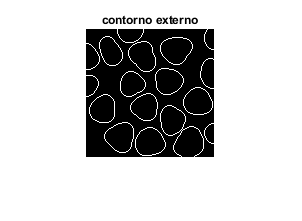


ee = strel('disk', 1);

dil = imdilate(im, ee);
ero = imerode(im,ee);

cex = imsubtract(dil, im);
cin = imsubtract(im, ero);

figure, imshow(cex), title('contorno externo')

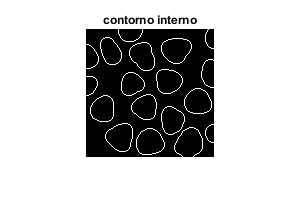

figure, imshow(cin), title('contorno interno')

## Laplaciano

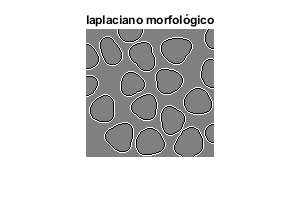

lap = imsubtract(double(cex), double(cin));

figure, imshow(lap, []), title('laplaciano morfológico')

## Contornos imagen danaus.tif

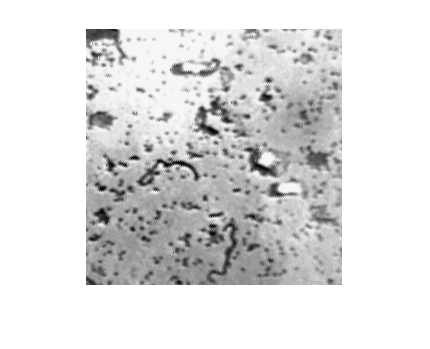

im = imread('danaus.tif');
imshow(im)

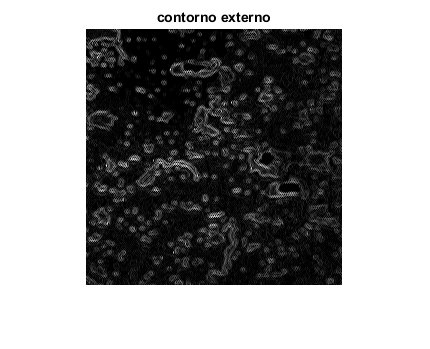



dil = imdilate(im, ee);
ero = imerode(im,ee);

cex = imsubtract(dil, im);
cin = imsubtract(im, ero);

figure, imshow(cex, []), title('contorno externo')

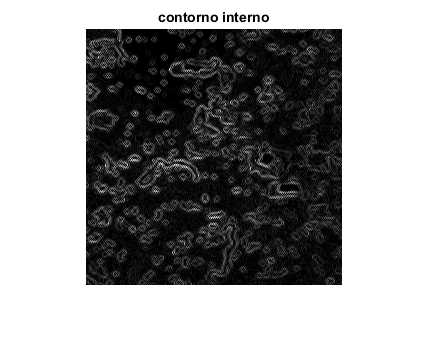

figure, imshow(cin, []), title('contorno interno')

## Dientes

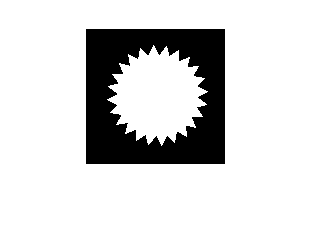

im = imread('gear.tif');
imshow(im)

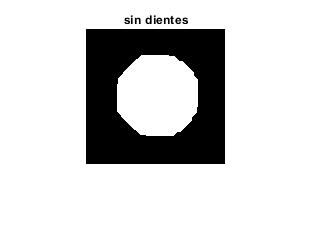


ee = strel('disk', 12);

op = imopen(im, ee);

figure, imshow(op), title('sin dientes')

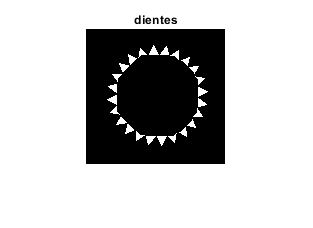

figure, imshow(im - op), title('dientes')

## Detección de fallos

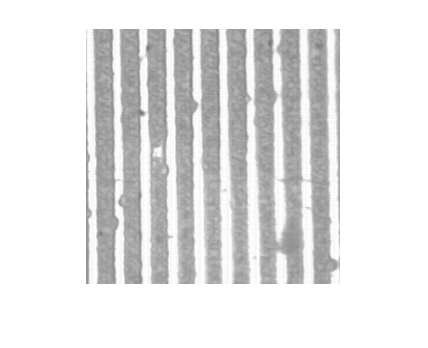

im = imread('r4x2_256.tif');
imshow(im)

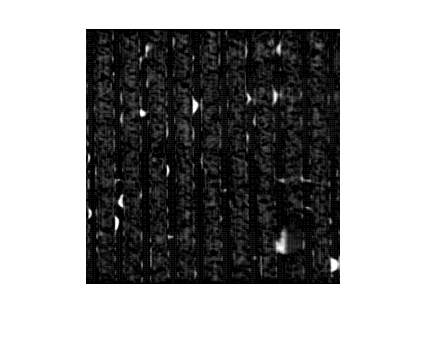


ee = strel('line', 30, 90);

cl = imclose(im, ee);
res = cl-im;
imshow(3*res)

## Máximos regionales

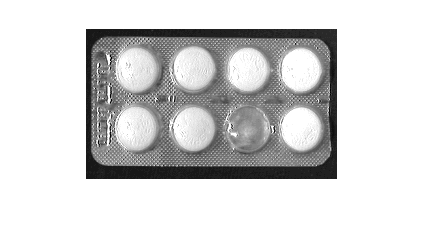

im = imread('astablet.tif');
imshow(im)

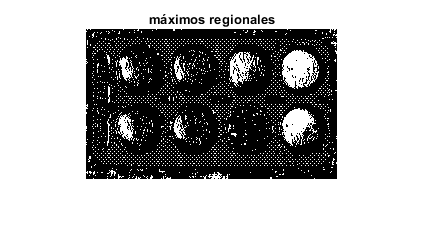


rm = imregionalmax(im);
figure, imshow(rm), title('máximos regionales')

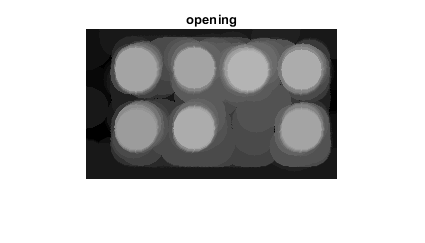


ee = strel('disk', 20, 0);

op = imopen(im, ee);

figure, imshow(op), title('opening')

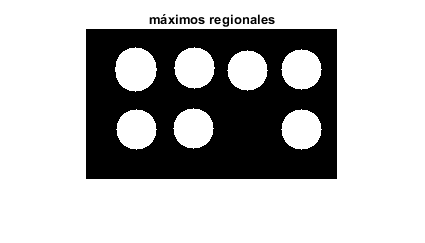


rm2 = imregionalmax(op);
figure, imshow(rm2), title('máximos regionales')

## Imagen Blood Cells

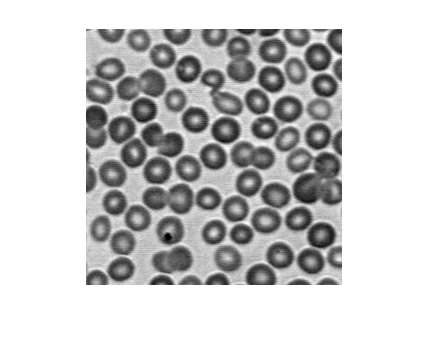

im = imread('bloodcells.tif');
imshow(im)

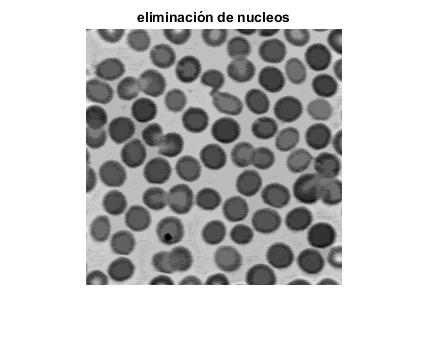


mark = im;
mark(2:end-1, 2:end-1) = 0;
mark(:,1) = 255;
mark(1,:) = 255;
mark(:,end) = 255;
mark(end,:) = 255;


imRec = imreconstruct(mark, im);
imshow(imRec), title('eliminación de nucleos')

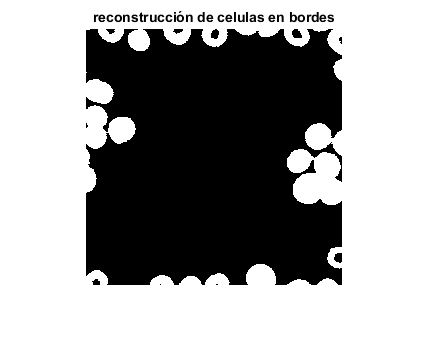


bw = im2bw(imRec,0.551);
notBw = logical(true(size(bw)) - bw);

mark2 = true(size(notBw));
mark2(2:end-1, 2:end-1) = 0;

imRec = imreconstruct(mark2, notBw);
imshow(imRec), title('reconstrucción de celulas en bordes')

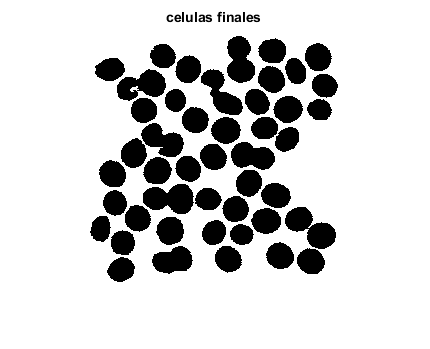


notBw = notBw - imRec;

bw = logical(true(size(notBw)) - notBw);
imshow(bw), title('celulas finales')